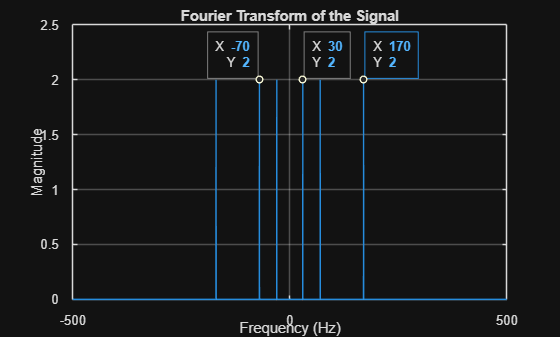

F_1 = 70; F_2 = 100; A_1 = 4; A_2 = 2;
F_s = 5e3; N = 10^7;

t = time_vec(F_s, N);

x_at = A_1*cos(2*pi*F_1*t).*(1+A_2*cos(2*pi*F_2*t));

% Compute the Fourier Transform of the signal
X_at = fftshift(fft(x_at));

f = frequency_vec(F_s, N);

figure;
plot(f, abs(X_at)/length(X_at));
xlim([-500 500]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of the Signal');
grid on;
 
ax = gca;
chart = ax.Children(1);
datatip(chart,-70,2,"Location","northwest");
datatip(chart,30,2);
datatip(chart,170,2);

Frekvenserne på spektret ses at være, -170, -70, -30, 30, 70, 170

2-3

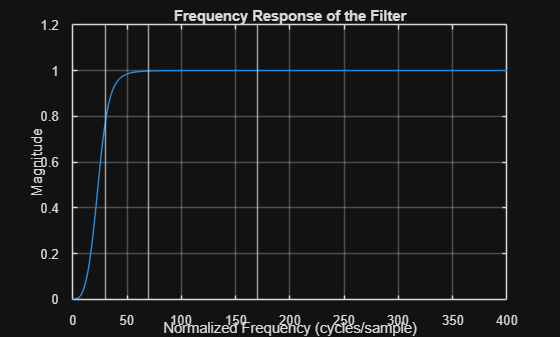

b = [0.915765 -2.747302 2.747302 -0.915767]; a = [1 -2.824127 2.663381 -0.838630];
[h, f] = freqz(b, a, 1024, F_s);

figure;
plot(f, abs(h));
xlim([0 400]);
xline([30 70 170]);
title('Frequency Response of the Filter');
xlabel('Normalized Frequency (cycles/sample)');
ylabel('Magnitude');
grid on;

H(z) beskriver et højpas filter

30Hz = 0.07, 70Hz = 0.719, 170 = 1.

4-1

clear; clc;

F_s = 2e3; f_c = 200;
omega_c = (2*pi*f_c)/F_s

omega_c = 0.6283

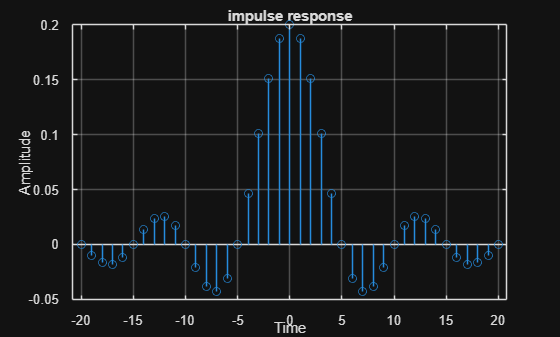

n = -20:20;

h = (omega_c/pi)*sinc((n*omega_c)/pi);

figure;
stem(-20:20, h);
xlabel('Time');
ylabel('Amplitude');
grid on;
title('impulse response');

h(0+1)

ans = -7.7963e-18

h(3+1)

ans = -0.0178

h(6+1)

ans = 0.0134

h(9+1)

ans = 0.0170

h(12+1)

ans = -0.0378

4-2

N_taps = 23;

syms K M
M_value = double(solve(N_taps == M + 1, M))

M_value = 22

K_value = double(solve(N_taps == 2*K + 1, K))

K_value = 11

For at forsinke signalet således at det er kausalt skal det forsinkes med K mændge, altså x[n-K]

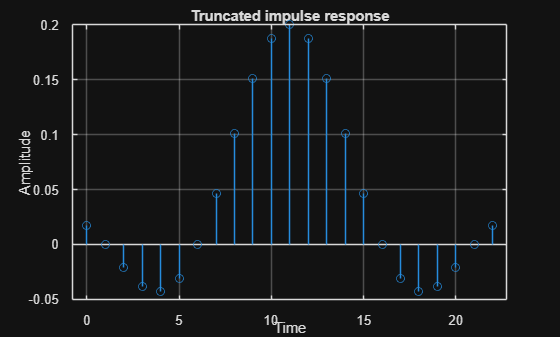

n = -K_value:K_value;

h_hp = (omega_c/pi)*sinc((n*omega_c)/pi);

figure;
stem(0:M_value, h_hp);
xlabel('Time');
ylabel('Amplitude');
title('Truncated impulse response');
grid on;

tf(h, 1, 1/F_s, 'Variable', 'z^-1')


ans =
 
  -7.796e-18 - 0.009847 z^-1 - 0.01682 z^-2 - 0.01781 z^-3 - 0.01169 z^-4 + 7.796e-18 z^-5 + 0.01336 z^-6 + 0.02329 z^-7 + 0.02523 z^-8 + 0.01701 z^-9 - 7.796e-18 z^-10 - 0.02079 z^-11 - 0.03784 z^-12 - 0.04325 z^-13 - 0.03118 z^-14 + 7.796e-18 z^-15 + 0.04677 z^-16 + 0.1009 z^-17 + 0.1514 z^-18 + 0.1871 z^-19 + 0.2 z^-20 + 0.1871 z^-21 + 0.1514 z^-22 + 0.1009 z^-23 + 0.04677 z^-24 + 7.796e-18 z^-25 - 0.03118 z^-26 - 0.04325 z^-27 - 0.03784 z^-28 - 0.02079 z^-29 - 7.796e-18 z^-30 + 0.01701 z^-31 + 0.02523 z^-32 + 0.02329 z^-33 + 0.01336 z^-34 + 7.796e-18 z^-35 - 0.01169 z^-36 - 0.01781 z^-37 - 0.01682 z^-38 - 0.009847 z^-39 - 7.796e-18 z^-40
 
Sample time: 0.0005 seconds
Discrete-time transfer function.


[H, f] = freqz(h, 1, 1024, F_s);

figure;
plot(f, 20*log10(abs(H)));
xlim([0 400]);
line([f_c f_c], [-3 -100], 'Color', 'r');
line([0 f_c], [-3 -3], 'Color', 'r');
xline([100 200 300]);
xlabel('Frequency (Hz)');
ylabel('Magnitide (dB)');
legend('Filter', 'F_c');
title('Frequency response of filter');
grid on;
 
FilterLine = findobj(gcf, "DisplayName", "Filter")

FilterLine =   Line (Filter) with properties:

              Color: [0.1490 0.5490 0.8660]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.9766 1.9531 2.9297 3.9062 4.8828 5.8594 6.8359 7.8125 8.7891 9.7656 10.7422 11.7188 12.6953 13.6719 14.6484 15.6250 16.6016 17.5781 18.5547 19.5312 20.5078 21.4844 22.4609 23.4375 24.4141 25.3906 26.3672 … ] (1×1024 double)
              YData: [-0.4308 -0.4299 -0.4274 -0.4232 -0.4174 -0.4099 -0.4008 -0.3902 -0.3781 -0.3645 -0.3495 -0.3331 -0.3155 -0.2967 -0.2767 -0.2557 -0.2337 -0.2108 -0.1872 -0.1628 -0.1379 -0.1124 -0.0866 -0.0604 -0.0340 -0.0075 … ] (1×1024 double)

  Show 

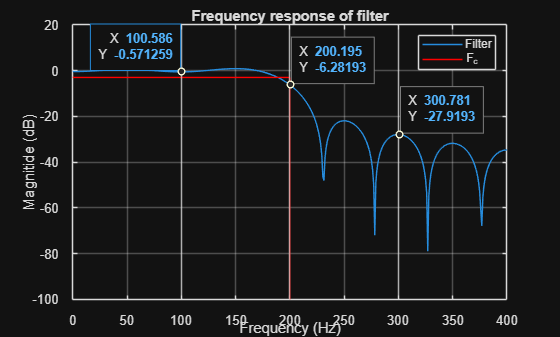

datatip(FilterLine,300.8,-27.92);
datatip(FilterLine,200.2,-6.282);
datatip(FilterLine,100.6,-0.5713,"Location","northwest");

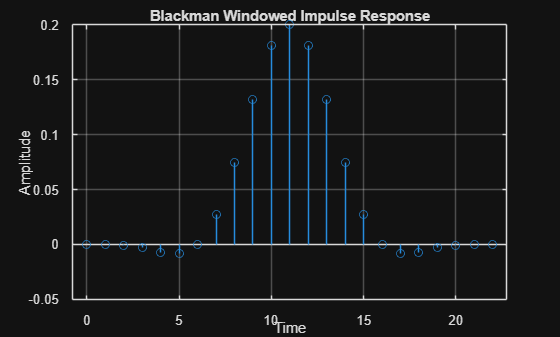

w_blackman = 0.42-0.5*cos(2*pi.*(0:M_value)/M_value)+0.08*cos(4*pi*(0:M_value)/M_value);

h_blackman = w_blackman .* h_hp; % Apply Blackman window to the impulse response
figure;
stem(0:M_value, h_blackman);
xlabel('Time');
ylabel('Amplitude');
title('Blackman Windowed Impulse Response');
grid on;

h(11+1)

ans = -0.0208

h(14+1)

ans = -0.0312

h(17+1)

ans = 0.1009

h(20+1)

ans = 0.2000

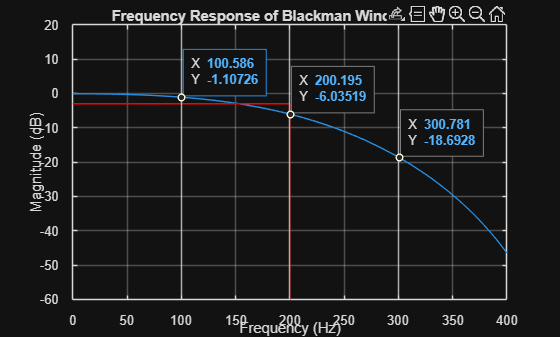


[h_b, f] = freqz(h_blackman, 1, 1024, F_s);

figure;
plot(f, 20*log10(abs(h_b)));
xlim([0 400]);
ylim([-60 20])
line([f_c f_c], [-3 -100], 'Color', 'r');
line([0 f_c], [-3 -3], 'Color', 'r');
xline([100 200 300]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response of Blackman Windowed Filter');
grid on;

ax2 = gca;
chart2 = ax2.Children(6);
datatip(chart2,300.8,-18.69);
datatip(chart2,200.2,-6.035);
datatip(chart2,100.6,-1.107);